# **Martin Zweig Investment Strategy with Markowitz Portfolio Optimization**

**Name: Ramnarain Nair, Student Number: 100468356, Date: 24/11/2021**

- 6 Companies that meet most of the criteria: **First American Financial, Whirlpool Coorporation, Clearfield Inc, Atlas Air WorldWide Holdings, Meritage Homes, Quest Diagnostics Incorporated. **An investment strategy that selects stocks by looking at growth potential and earnings. The strategy also considers the leverage taken on by firms.

- Benchmark : S&P 500

- Risk-Free : 13-week T-Bills

- Use Markowitz Portfolio Optimization to determine the portfolio that maximizes the Sharpe Ratio

- Also, looking into the future by investing a green ETF fund (QCLN)

## Side By Side Comparison/Analysis

1. Plots, Descriptive Statistics & Returns

iniDate = '28-May-2010';
endate= '31-Oct-2021';
symbols = {'FAF','CLFD','WHR','AAWW','MTH','DGX','QCLN','^GSPC','^IRX'}

symbols = 1×9 cell array
    {'FAF'}    {'CLFD'}    {'WHR'}    {'AAWW'}    {'MTH'}    {'DGX'}    {'QCLN'}    {'^GSPC'}    {'^IRX'}


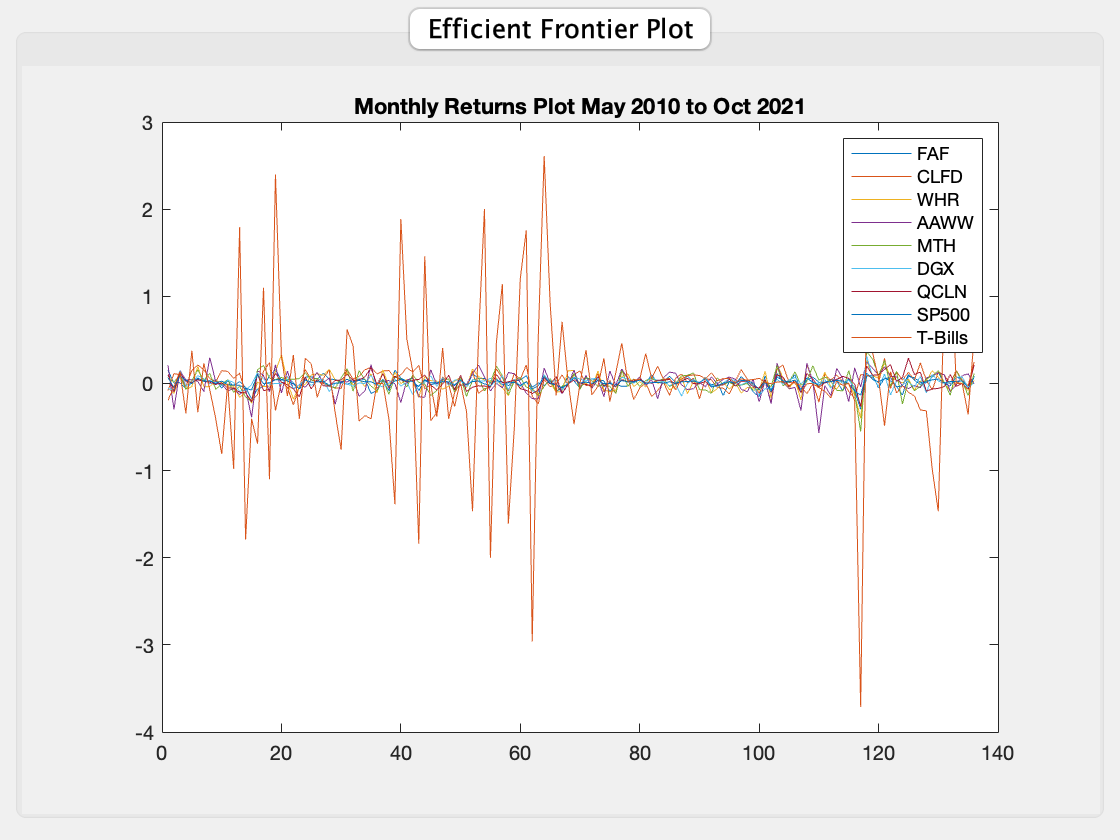

returns = [];
price = [];

% Computing Monthly Returns 
for symbol = 1:numel(symbols)
    stockname = symbols{symbol};
    stockdata = getMarketDataViaYahoo(stockname,iniDate,endate, '1mo');   
    stockts = timeseries([stockdata.Close], datestr(stockdata(:,1).Date));
    stockts.Name = symbols(symbol);
    price_stock=stockdata.Close; 
    T=length(price_stock);
    r_stock= log(price_stock(2:T) ./ price_stock(1:T-1));
    returns = [returns r_stock];
    price = [price price_stock];
end

% Plot of Returns
plot(returns)
title('Monthly Returns Plot May 2010 to Oct 2021')
legend('FAF','CLFD','WHR','AAWW','MTH','DGX','QCLN','SP500', 'T-Bills')

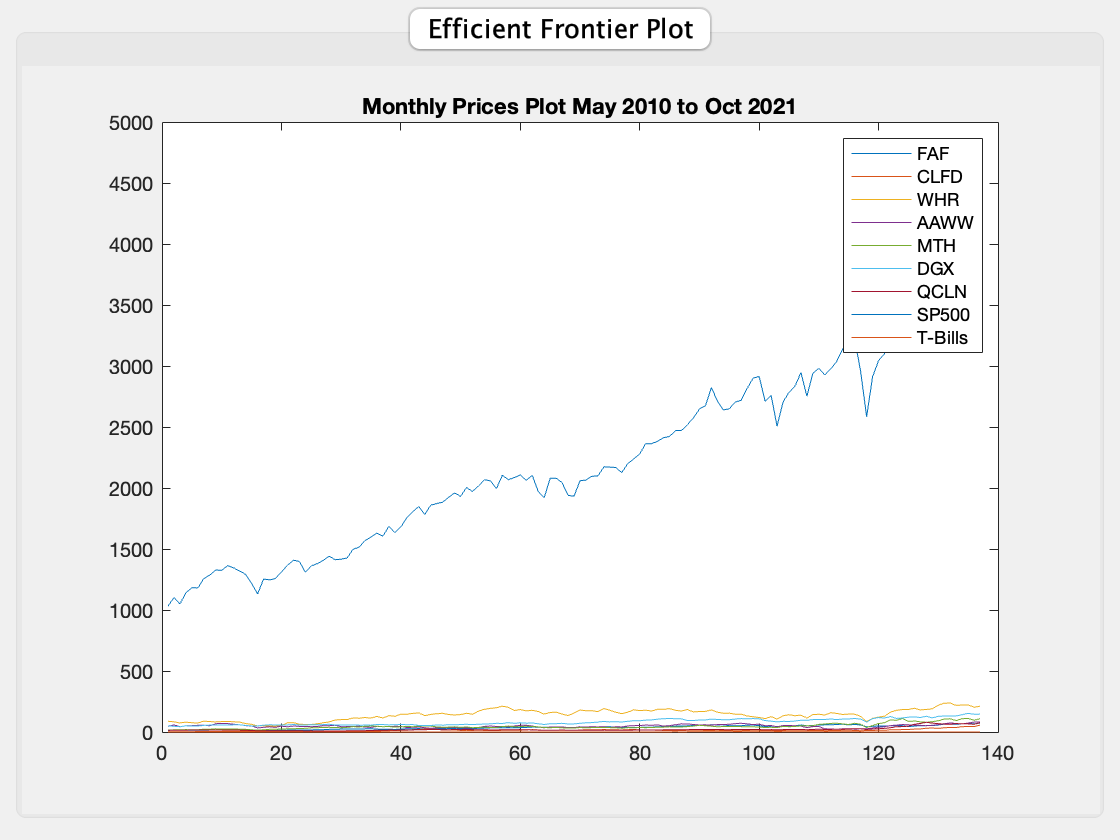


% Plot of Prices
plot(price)
title('Monthly Prices Plot May 2010 to Oct 2021')
legend('FAF','CLFD','WHR','AAWW','MTH','DGX','QCLN','SP500', 'T-Bills')

% Monthly Returns Statistics
new_table_month = [];
for ret = 1:numel(symbols)
    T4 = size(returns(:,ret),1);
    ww=returns(:,ret);
    T2= table(T4, mean(ww), max (ww), min(ww), std(ww), skewness(ww), kurtosis(ww));
    T2.Properties.VariableNames = {'SampleSize','Mean', 'Max', 'Min', 'Std', 'Skewness', 'Kurtosis'};
    vt = {symbols{ret}};
    T2.Properties.RowNames = vt;
    new_table_month = [new_table_month; T2];
end

new_table_month

new_table_month = 9×7 table
             SampleSize       Mean         Max        Min         Std       Skewness     Kurtosis
             __________    __________    _______    ________    ________    _________    ________

    FAF         136          0.012885    0.15674    -0.29742    0.068376     -0.98487     5.4819 
    CLFD        136          0.022722    0.28911    -0.38192     0.12239     -0.55462     3.3249 
    WHR         136         0.0064394    0.33017    -0.39892     0.10228    -0.058366     4.5837 
    AAWW        136         0.0039353    0.29552    -0.56869     0.13048     -0.83528     5.2612 
    MTH         136          0.013961    0.36437    -0.55282

% Computing the yearly returns
yearly_returns = [];

for stk = 1:numel(symbols)
    stock_price = price(:, stk);
    stock_Y = stock_price(1:12:T);
    TY=size(stock_Y,1);
    retY_stock = log(stock_Y(2:TY) ./ stock_Y(1:TY-1));
    yearly_returns = [yearly_returns retY_stock];
end

yearly_returns

yearly_returns =     0.2104    1.0260   -0.0769    0.2254    0.3262    0.1718    0.1319    0.2479   -2.4277
    0.0804   -0.3992   -0.2849   -0.3132    0.4084    0.0134   -0.4961    0.0310    1.6740
    0.2620    0.6721    0.6259    0.0057    0.2449    0.0121    0.4172    0.1648   -0.9808
    0.2318    0.5779    0.1967   -0.1719   -0.0269   -0.0325    0.3746    0.1991   -0.4055
    0.2919   -0.0538    0.2175    0.3998    0.1094    0.2116   -0.1073    0.0512   -0.6931
    0.0778    0.1173   -0.0377   -0.2828   -0.2267    0.1156   -0.2560    0.0172    3.2108
    0.1054   -0.3040    0.1397    0.2304    0.1170    0.3115    0.2358    0.1438    1.3873
    0.1461   -0.1778   -0.2703    0.3184    0.0406   -0.0110    0.0745    0.1149    0.6383
    0.0376    0.1816   -0.0268   -0.4739    0.1554   -0.0768    0.0798    0.0790    0.0792
   -0.1118    0.0522   -0.0944   -0.0367    0.3938    0.1127    0.3417    0.0525   -2.7130


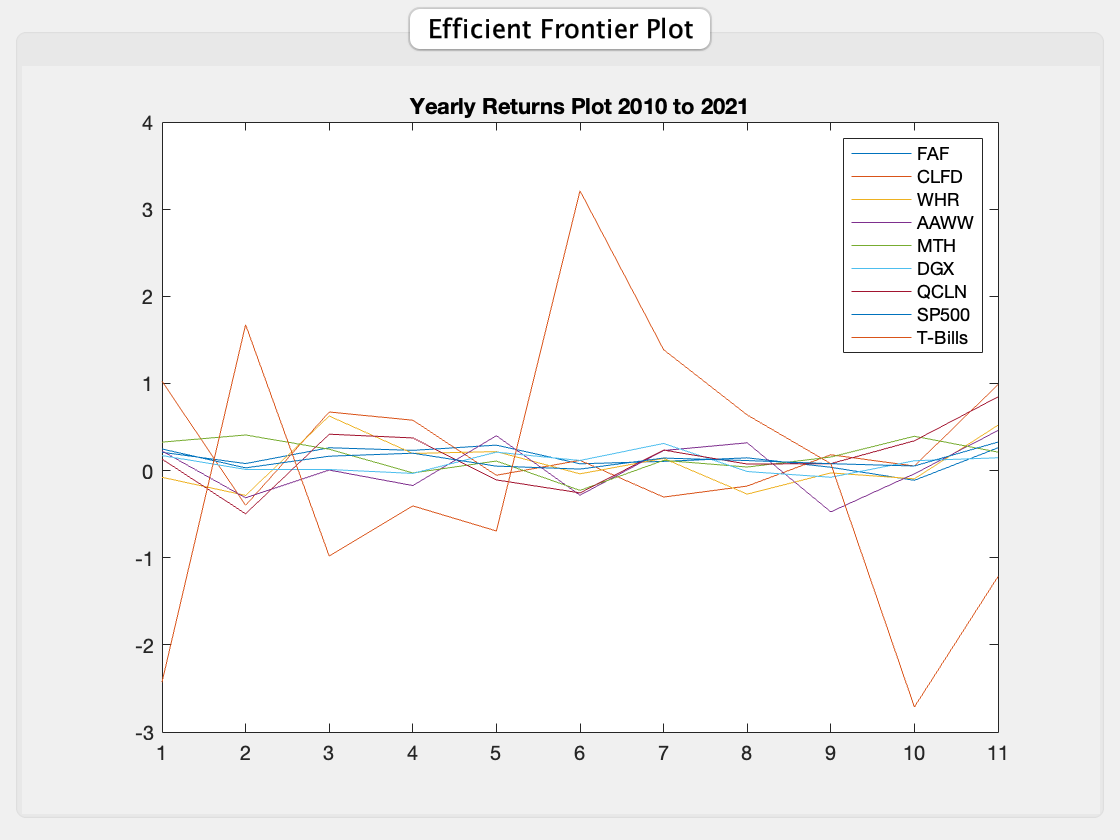


% Plot of Yearly Returns
plot(yearly_returns)
title('Yearly Returns Plot 2010 to 2021')
legend('FAF','CLFD','WHR','AAWW','MTH','DGX','QCLN','SP500', 'T-Bills')

% Yearly Return Statistics
new_table_year = [];

for ret_y = 1:numel(symbols)
    TR = size(yearly_returns(:, ret_y),1);
    xx=yearly_returns(:, ret_y);
    T4=table(TR ,mean(xx), max(xx),min(xx), std(xx),skewness(xx), kurtosis(xx));
    T4.Properties.VariableNames = {'Sample_Size','Mean','Max','Min', 'STD', 'Skewness', 'Kurtosis'};
    vs={symbols{ret_y}};
    T4.Properties.RowNames=vs;
    new_table_year = [new_table_year; T4];
end

new_table_year

new_table_year = 9×7 table
             Sample_Size      Mean        Max         Min         STD       Skewness    Kurtosis
             ___________    ________    _______    _________    ________    ________    ________

    FAF          11          0.14479     0.2919      -0.1118     0.12179    -0.66446     2.7113 
    CLFD         11          0.24355      1.026     -0.39921     0.49955     0.39175     1.8154 
    WHR          11         0.082663    0.62586      -0.2849       0.294      0.5865     2.3577 
    AAWW         11         0.032763    0.45923     -0.47386     0.31586    -0.15523     1.6873 
    MTH          11          0.15947    0.40842     -0.22665     0.

% Quantile Payoffs
new_table_quantiles = [];

% Possible 1-year payoffs per $100 invested
for quant = 1:numel(symbols)
    qystock=quantile(yearly_returns(:, quant),[0.01  0.05 0.50 0.95]);
    payoff= 100 .* (1+qystock);
    T1=table(payoff(1,1), payoff(1,2), payoff(1,3), payoff(1,4));
    T1.Properties.VariableNames = { 'One_percent','Five_percent','Fifty_percent', 'NinetyFive_percent'};
    T1.Properties.RowNames = {symbols{quant}};
    new_table_quantiles = [new_table_quantiles; T1];
end

new_table_quantiles

new_table_quantiles = 9×4 table
             One_percent    Five_percent    Fifty_percent    NinetyFive_percent
             ___________    ____________    _____________    __________________

    FAF         88.82          89.567          114.61              129.04      
    CLFD       60.079          60.555          111.73               202.4      
    WHR         71.51          71.583          97.318              162.06      
    AAWW       52.614          53.417          100.57              145.63      
    MTH        77.335          78.334          115.54              140.77      
    DGX        92.317          92.539          111.27              130.65      
    QCLN       50.389          51.589          113.19              182.4

% Sharpe Ratio Computation
excess_returns = [];
new_table_sharpe = [];

% Computes the excess returns
for sharpe = 1:numel(symbols)-1
    er_stock = returns(:, sharpe) - returns(:, end);
    excess_returns = [excess_returns er_stock];
end

% Monthly Data Sharpe Ratios
ret=[excess_returns(:, 1),excess_returns(:, 2),excess_returns(:, 3),excess_returns(:, 4),excess_returns(:, 5),excess_returns(:, 6),excess_returns(:, 7), excess_returns(:, 8)];
mu = mean(ret);
sigma= std(ret);
SR =  mu./sigma;  % Sharpe ratio
SR_Ann = SR*sqrt(12);
SRT = SR*sqrt(T);           % T-statistic H0: SR = 0
Pvalue = 1-tcdf(abs(SRT),T-1); % Probability of Null Hypothesis one-tail test
TPvalue = min(0.01, 1/T)*ones(length(SRT),1); % Target p-value for rejecting the null hypothesis
Ttstat = abs(tinv(TPvalue,T-1)).*ones(length(SRT),1);  % Target t-statistic for rejecting the null hypothesis  
Name = {'FAF';'CLFD';'WHR';'AAWW';'MTH';'DGX';'QCLN';'SP500'};
T1M=table(SR',SR_Ann',SRT',Pvalue',TPvalue,Ttstat,'RowNames',Name);
T1M.Properties.VariableNames = {'Sharpe_Ratio','Annualized Sharpe Ratio','T_statistic','P_Value','TargetPval','Target_tstat'}

T1M = 8×6 table
             Sharpe_Ratio    Annualized Sharpe Ratio    T_statistic    P_Value    TargetPval    Target_tstat
             ____________    _______________________    ___________    _______    __________    ____________

    FAF        0.027359             0.094774              0.32023      0.37464    0.0072993        2.4738   
    CLFD       0.038254              0.13252              0.44776      0.32752    0.0072993        2.4738   
    WHR        0.019337             0.066984              0.22633      0.41064    0.0072993        2.4738   
    AAWW       0.015952             0.055258              0.18671      0.42608    0.0072993        2.4738   
    MTH         0.02885             0.09


% Annualised sharpe ratio for individual stocks
SRT_Ann = SR_Ann*sqrt(TY); 
Pvalue_Ann = 1-tcdf(abs(SRT_Ann),TY-1); % Probability of Null Hypothesis one-tail test
TPvalue_Ann = min(0.01, 1/TY)*ones(length(SRT_Ann),1); % Target p-value for rejecting the null hypothesis
Ttstat_Ann = abs(tinv(TPvalue_Ann,TY-1)).*ones(length(SRT),1);  % Target t-statistic for rejecting the null hypothesis 
T1M_Ann =table(SR_Ann',SRT_Ann',Pvalue_Ann',TPvalue_Ann,Ttstat_Ann,'RowNames',Name);
T1M_Ann.Properties.VariableNames = {'Annualized Sharpe Ratio','T_statistic','P_Value','TargetPval','Target_tstat'}

T1M_Ann = 8×5 table
             Annualized Sharpe Ratio    T_statistic    P_Value    TargetPval    Target_tstat
             _______________________    ___________    _______    __________    ____________

    FAF             0.094774              0.32831      0.37442       0.01          2.7181   
    CLFD             0.13252              0.45905      0.32757       0.01          2.7181   
    WHR             0.066984              0.23204      0.41038       0.01          2.7181   
    AAWW            0.055258              0.19142      0.42584       0.01          2.7181   
    MTH             0.099939               0.3462      0.36786       0.01          2.7181   
    DGX             0.073246              0.25373      0

## Markowitz Portfolio Optimization on Monthly Data

% Returns the weights of each stock in the portfolio
tickers = {'FAF','CLFD','WHR','AAWW','MTH','DGX', 'QCLN'}

tickers = 1×7 cell array
    {'FAF'}    {'CLFD'}    {'WHR'}    {'AAWW'}    {'MTH'}    {'DGX'}    {'QCLN'}


p = Portfolio('AssetList', tickers, 'RiskFreeRate', ...
    mean(returns(:,end)));
p = estimateAssetMoments(p, returns(:, 1:7));
p = setDefaultConstraints(p);
w1 = estimateMaxSharpeRatio(p)

w1 =     0.4380
    0.1939
    0.0000
    0.0000
    0.0000
    0.2293
    0.1388


[risk1, ret1] = estimatePortMoments(p, w1)

risk1 = 0.0542

ret1 = 0.0137

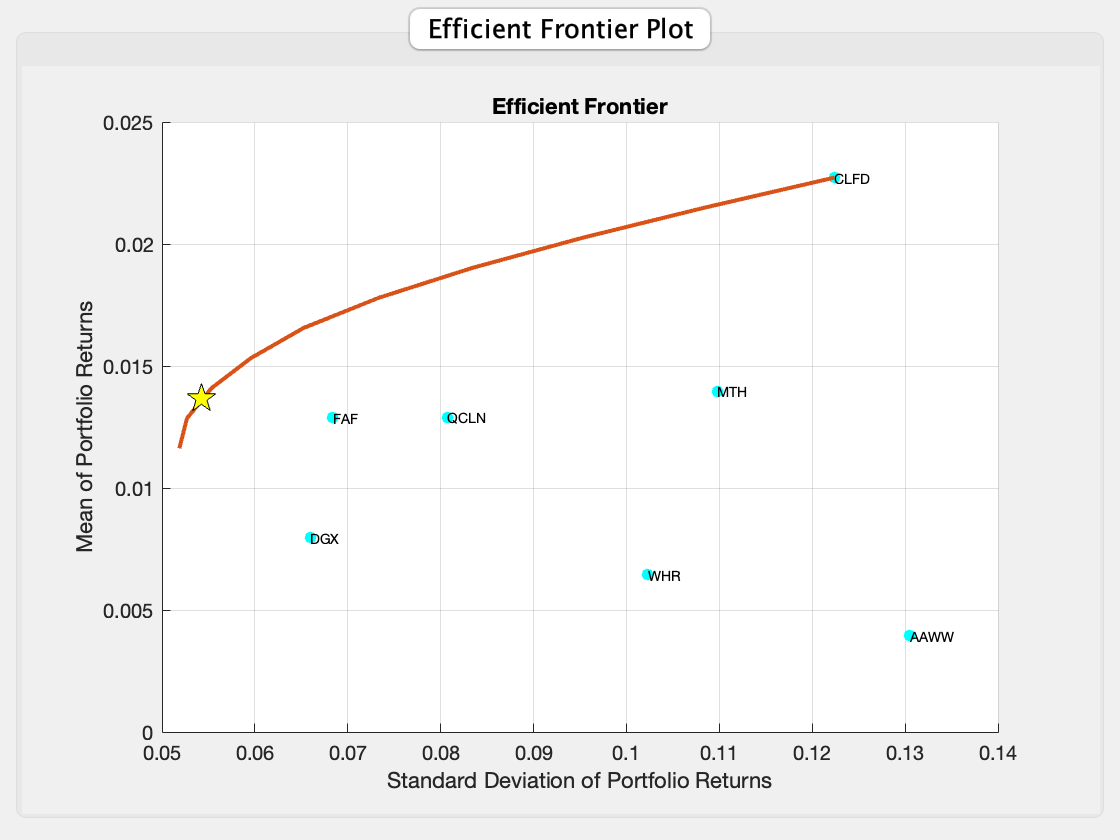

% Plots the efficient frontier, with the optimal portfolio values
f = figure;
tabgp = uitabgroup(f); % Define tab group
tab1 = uitab(tabgp,'Title','Efficient Frontier Plot'); % Create tab
ax = axes('Parent', tab1);
% Extract asset moments from portfolio and store in m and cov
[m, cov] = getAssetMoments(p); 
scatter(ax,sqrt(diag(cov)), m,'oc','filled'); % Plot mean and s.d.
xlabel('Risk');
ylabel('Expected Return');
text(sqrt(diag(cov)),m,tickers,'FontSize',7); % Label ticker names
hold on;
[risk2, ret2]  = plotFrontier(p,10);
plot(risk1,ret1,'p','markers',15,'MarkerEdgeColor','k',...
                'MarkerFaceColor','y');
hold off

Stock = tickers';
Weights = w1*100;
data = table(Stock, Weights)

data = 7×2 table
     Stock       Weights  
    ________    __________

    {'FAF' }        43.798
    {'CLFD'}        19.391
    {'WHR' }     2.072e-11
    {'AAWW'}    1.0043e-09
    {'MTH' }    7.6453e-11
    {'DGX' }        22.934
    {'QCLN'}        13.877


## Analysis of Investment Strategy

% Calculating the returns and volatility of the portfolio based on
% the portfolio optimization weights
return_portfolio = 0.437978.*returns(:,1) + 0.193914.*returns(:,2)+0.229338.*returns(:,6)+0.138769.*returns(:,7);
%return_portfolio = 0.25.*returns(:,1) + 0.25.*returns(:,2)+0.25.*returns(:,6) + 0.25.*returns(:,7);
mean_port = mean(return_portfolio)

mean_port = 0.0137

std_port = std(return_portfolio)

std_port = 0.0542


mean_market = mean(returns(:,8))

mean_market = 0.0110

std_market = std(returns(:,8))

std_market = 0.0392

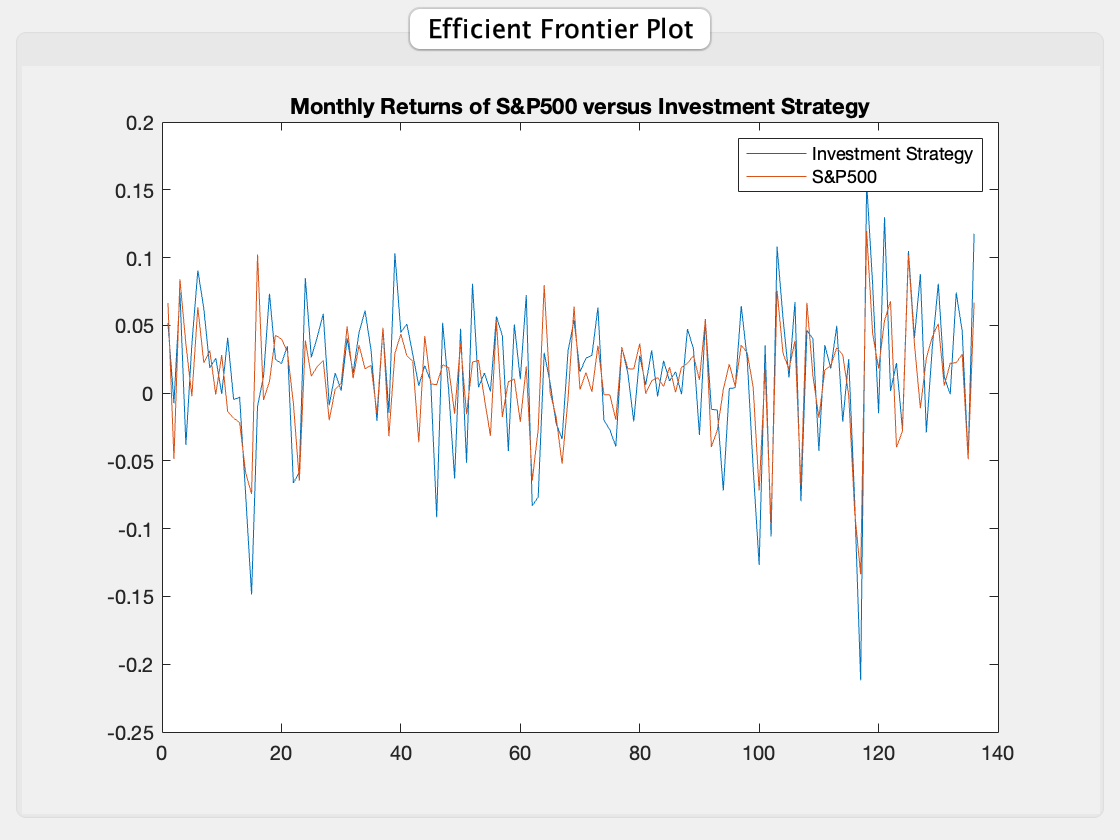

% Plots the monthly returns of the investment strategy
plot(return_portfolio)
hold on
plot(returns(:,8))
hold off
title('Monthly Returns of S&P500 versus Investment Strategy')
legend('Investment Strategy', 'S&P500')

% Monthly sharpe ratio of investment strategy
er_port = 43.7978.*excess_returns(:,1) + 19.3914.*excess_returns(:,2) + 22.9338.*excess_returns(:,6) + 13.8769.*excess_returns(:,7)

er_port =    24.5845
    2.8961
   -6.3935
   30.4889
  -33.8832
   42.0752
  -16.9312
    8.9978
   43.1270
   81.0268


mean_er = mean(er_port)

mean_er = 2.2961

std_er = std(er_port)

std_er = 81.4782

SR =  mean_er./std_er;            % Sharpe ratio
SR_Ann = SR*sqrt(12); % Annualised sharpe ratio
SRT = SR*sqrt(T);           % T-statistic H0: SR = 0
Pvalue = 1-tcdf(abs(SRT),T-1); % Probability of Null Hypothesis one-tail test
TPvalue = min(0.01, 1/T)*ones(length(SRT),1); % Target p-value for rejecting the null hypothesis
Ttstat = abs(tinv(TPvalue,T-1)).*ones(length(SRT),1);  % Target t-statistic for rejecting the null hypothesis  
Name = {'Investment Strategy'};
T1M=table(SR',SR_Ann',SRT',Pvalue',TPvalue,Ttstat,'RowNames',Name);
T1M.Properties.VariableNames = {'Sharpe_Ratio','Annualized Sharpe Ratio','T_statistic','P_Value','TargetPval','Target_tstat'}

T1M = 1×6 table
                           Sharpe_Ratio    Annualized Sharpe Ratio    T_statistic    P_Value    TargetPval    Target_tstat
                           ____________    _______________________    ___________    _______    __________    ____________

    Investment Strategy      0.028181             0.097621              0.32985      0.37101    0.0072993        2.4738   



% Annualized sharpe ratio of investment strategy
SRT_Ann = SR_Ann*sqrt(TY); 
Pvalue_Ann = 1-tcdf(abs(SRT_Ann),TY-1); % Probability of Null Hypothesis one-tail test
TPvalue_Ann = min(0.01, 1/TY)*ones(length(SRT_Ann),1); % Target p-value for rejecting the null hypothesis
Ttstat_Ann = abs(tinv(TPvalue_Ann,TY-1)).*ones(length(SRT),1);  % Target t-statistic for rejecting the null hypothesis 
T1M_Ann =table(SR_Ann',SRT_Ann',Pvalue_Ann',TPvalue_Ann,Ttstat_Ann,'RowNames',Name);
T1M_Ann.Properties.VariableNames = {'Annualized Sharpe Ratio','T_statistic','P_Value','TargetPval','Target_tstat'}

T1M_Ann = 1×5 table
                           Annualized Sharpe Ratio    T_statistic    P_Value    TargetPval    Target_tstat
                           _______________________    ___________    _______    __________    ____________

    Investment Strategy           0.097621              0.33817      0.3708        0.01          2.7181   


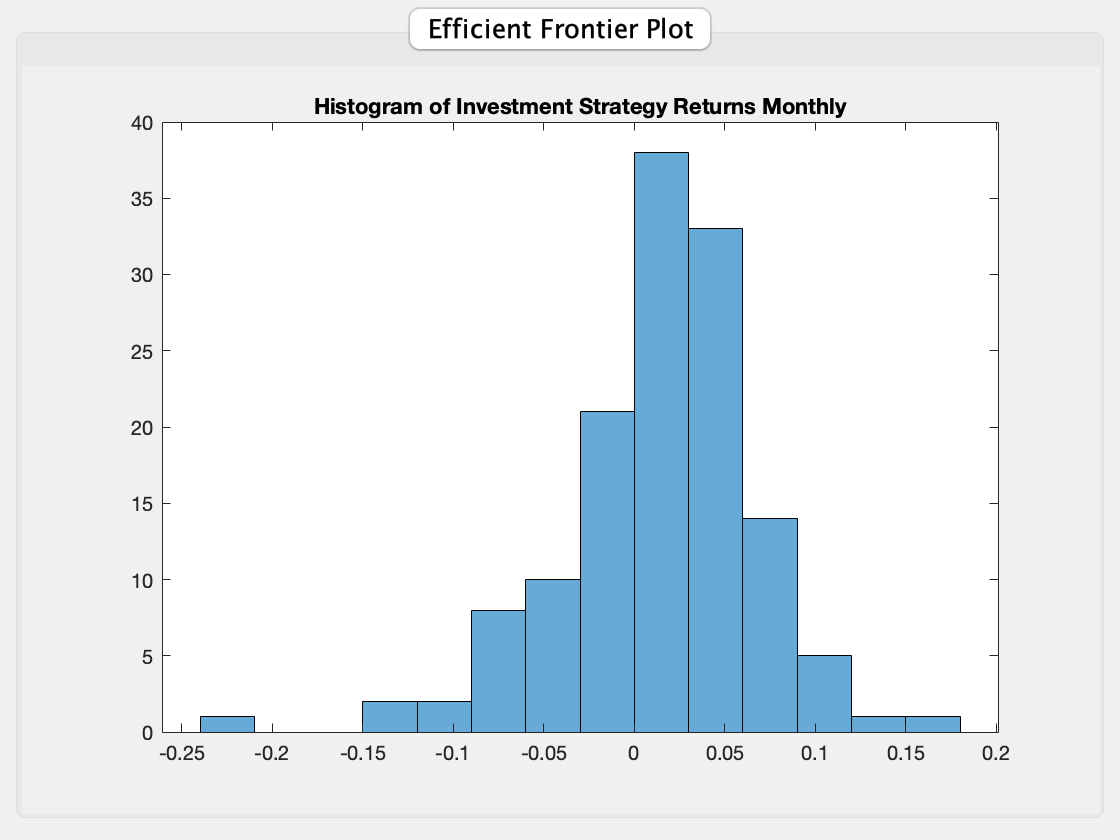

% histogram of investment strategy returns
histogram(return_portfolio)
title('Histogram of Investment Strategy Returns Monthly')

% Annualized data for benchmark and investment strategy
mean_market_ann = mean_market*12

mean_market_ann = 0.1321

std_market_ann = std_market*sqrt(12)

std_market_ann = 0.1360


mean_port_ann = mean_port*12

mean_port_ann = 0.1640

std_port_ann = std_port*sqrt(12)

std_port_ann = 0.1878

% Vector of returns of investment strategy for each year
ann_return_port = return_portfolio.*12;
ann_return_markt = returns(:,8).*12;

annualised_port = [];
annualised_market = [];
for mn = 1:12:length(ann_return_port)-4
    annualised_port = [annualised_port mean(ann_return_port(mn:mn+11))];
    annualised_market = [annualised_market mean(ann_return_markt(mn:mn+11))];
end

annualised_port'

ans =     0.3488
   -0.1080
    0.3058
    0.2581
    0.1510
    0.0478
    0.0914
    0.0373
    0.0451
    0.0344


annualised_market'

ans =     0.2479
    0.0310
    0.1648
    0.1991
    0.0512
    0.0172
    0.1438
    0.1149
    0.0790
    0.0525


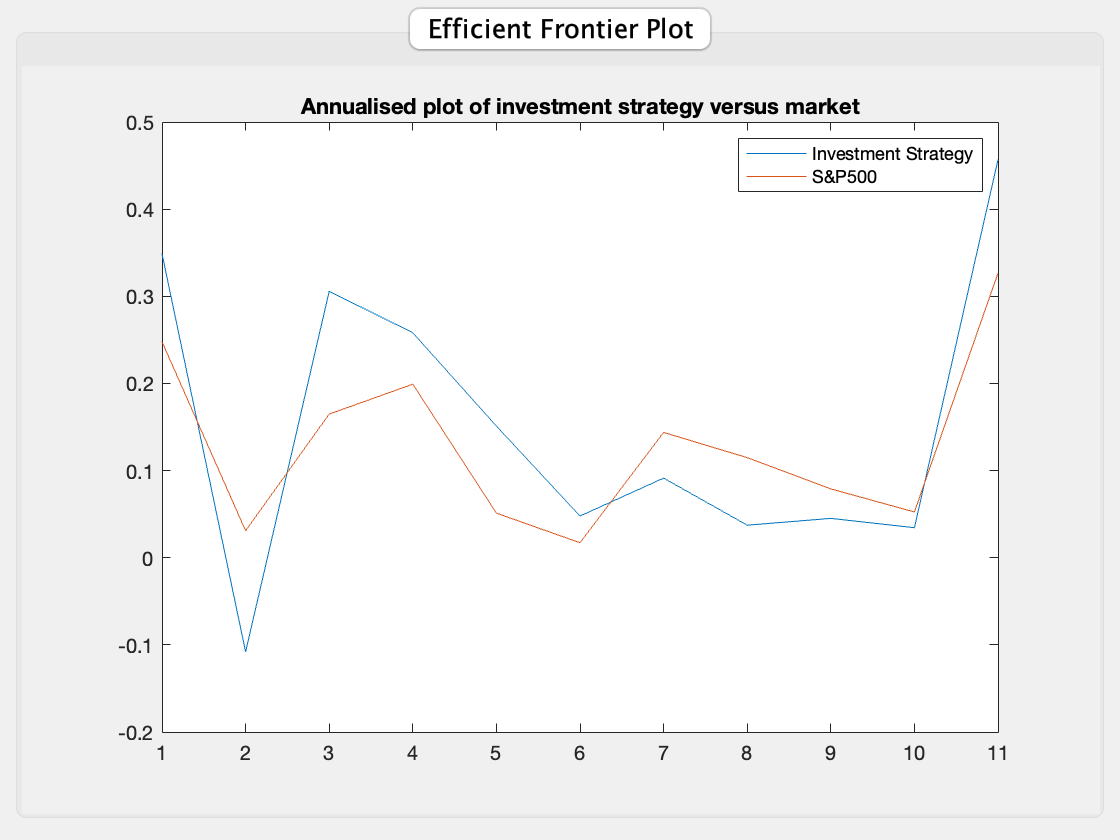


% Plot of investment strategy returns and benchmark
plot(annualised_port')
hold on
plot(annualised_market')
hold off
title('Annualised plot of investment strategy versus market')
legend('Investment Strategy', 'S&P500')